# Assignment #2: ECMS

## Group information

Group number: 09

Students:

- Ulugbek Rakhmatullaev, s330568

- Nozima Yakubova, s344733

- Nicolo Ferruggia, s349151

## Load the cycle and vehicle data

In this section, the **data** necessary to advance the project are entered. Subsequently, the subfolders entitled "utilities," "model," and "data" are appended to the aforementioned path. Specifically, the mission, which is an **ARDC**-type cycle that takes into account various traffic conditions, including suburbs and highways in addition to the city, is loaded. The subsequent graph is a representation of vehicle speed (in meters per second) as a function of time. This is followed by the acceleration graph (in meters per second squared).

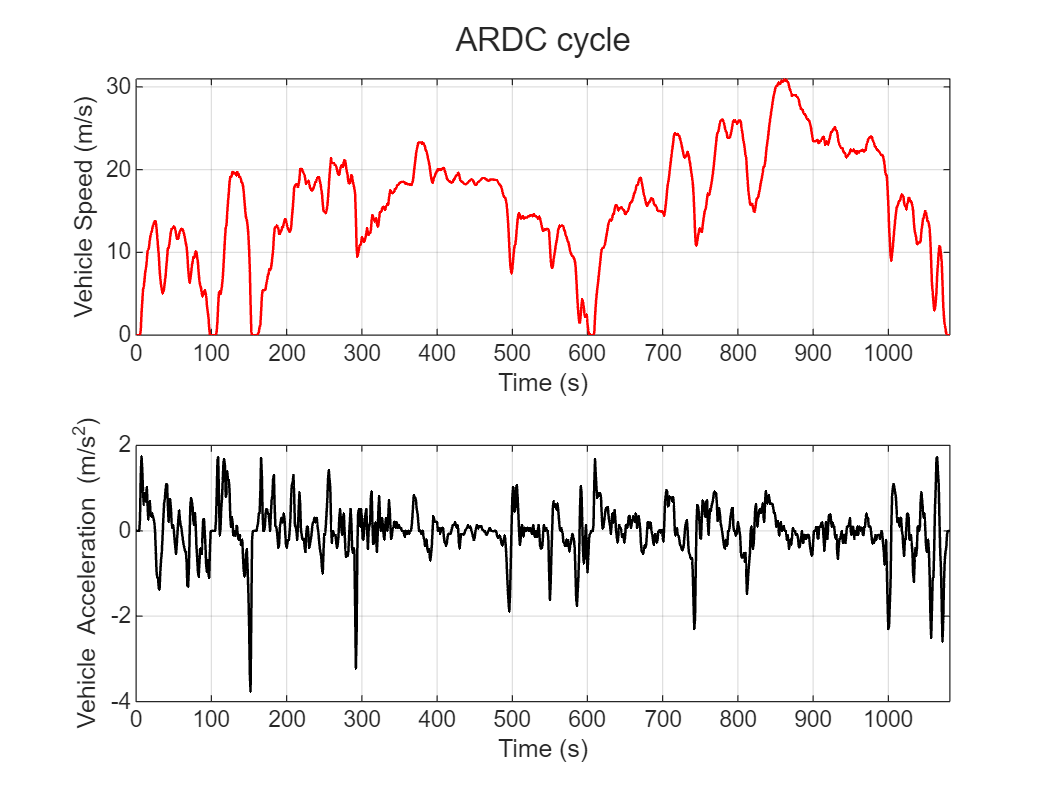

clc; clear; close all; % Housekeeping

% Add the folders to Path
addpath("utilities");
addpath("models");
addpath("data");

mission = load("ARDC.mat");         % Load the ARDC cycle
time = mission.time_s;              % [s]
vehSpd = mission.speed_km_h./3.6;   % [m/s]
vehAcc = mission.acceleration_m_s2; % [m/s^2]

% Create the figure of ARDC cycle
t = tiledlayout(2,1);

nexttile(1)
% Plot the vehicle speed
plot(time, vehSpd, LineStyle="-", Color='r', LineWidth=1);
xlabel("Time (s)");
ylabel("Vehicle Speed (m/s)");
grid on
xlim([time(1) time(end)])

nexttile(2)
% Plot the vehicle acceleration
plot(time, vehAcc, LineStyle="-", Color='k', LineWidth=1);
xlabel("Time (s)");
ylabel("Vehicle Acceleration (m/s^2)");
grid on
xlim([time(1) time(end)])

title(t, "ARDC cycle");

## Interval Selection for Bisection Algorithm

In order to develop a bisection algorithm for controlling the vehicle's State of Charge (SoC), two equivalence factors, `a` and `b`, are required such that:

- At `a`, the difference between final and initial SoC is **negative**.

- At `b`, the difference is **positive**.

These two points provide a valid interval for the bisection method, ensuring convergence toward the desired SoC.

Vehicle data is loaded and scaled according to group parameters.

veh = load("data\vehData.mat");

motPwr = 70000;    % [W]
engPwr = 66000;    % [W]
battEnrg = 1260;   % [Wh]
veh = scaleVehData(veh, motPwr, engPwr, battEnrg);

### Identifying Suitable Equivalence Factors

Through a series of trial runs, two equivalence factors were found that satisfy the bisection conditions.

Equivalence factor '**a**' (expected ΔSoC - **negative**)

eqFactor_a = 2.6;
psiA = run_simulation(eqFactor_a, time, vehSpd, vehAcc, veh);
fprintf("Negative ΔSoC: %.4f ", psiA);

Negative ΔSoC: -0.1383 

Equivalence factor '**b**' (expected ΔSoC - **positive**)

eqFactor_b = 2.7;
psiB = run_simulation(eqFactor_b, time, vehSpd, vehAcc, veh);
fprintf("Positive ΔSoC: %.4f ", psiB);

Positive ΔSoC: 0.2572 

Lines 40 and 43 run the simulation (the loop) and gets as an output **ΔSoC** for given equivalence factor using local function `run_simulation()`.

## Equivalence Factor Calibration using Bisection Algorithm

In order to optimize the **Equivalent Consumption Minimization Strategy (ECMS)** control, the goal is to maintain the final State of Charge (SoC) very close to its initial value.

#### In our case:

 - The initial SoC is set at **0.6**.

 - The objective is to achieve a final SoC within the range: **0.595 < SoC < 0.605**.

To accomplish this, a bisection algorithm is developed. By setting a tolerance threshold, the algorithm iteratively refines the equivalence factor to minimize the SoC difference.

The values of equivalence factors `a` and `b` used for the initial interval are those identified above:

 - `a = 2.6` (gets a negative ΔSoC)

 - `b = 2.7` (gets a positive ΔSoC)

#### Bisection Algorithm Implementation

The following function implements the bisection method to find the optimal equivalence factor `s_opt` that minimizes the difference between final and initial SoC within the desired tolerance.

function eqFactor_opt = bisectionAlgorithm(vehSpd, vehAcc, time, veh)
    % Tolerance for SoC difference

Optimal Equivalence Factor: 2.6375 

    tol = 0.005;


ΔSoC: -0.0045 

    % Initial bounds for equivalence factor
    a = 2.6;
    b = 2.7;

    while true
        % Calculate midpoint equivalence factor
        s = (a + b) / 2;

        % Evaluate SoC difference using midpoint factor
        psiC = run_simulation(s, time, vehSpd, vehAcc, veh);

        % Check if within tolerance
        if abs(psiC) < tol
            eqFactor_opt = s;  % Optimal equivalence factor found
            break
        else
            % Update bounds
            if psiC > 0
                b = s;  % If positive, update upper bound

Fuel consumption: 0.51 kg


            elseif psiC < 0

Fuel economy: 3.75 l/100km


                a = s;  % If negative, update lower bound

Final SOC: 0.596


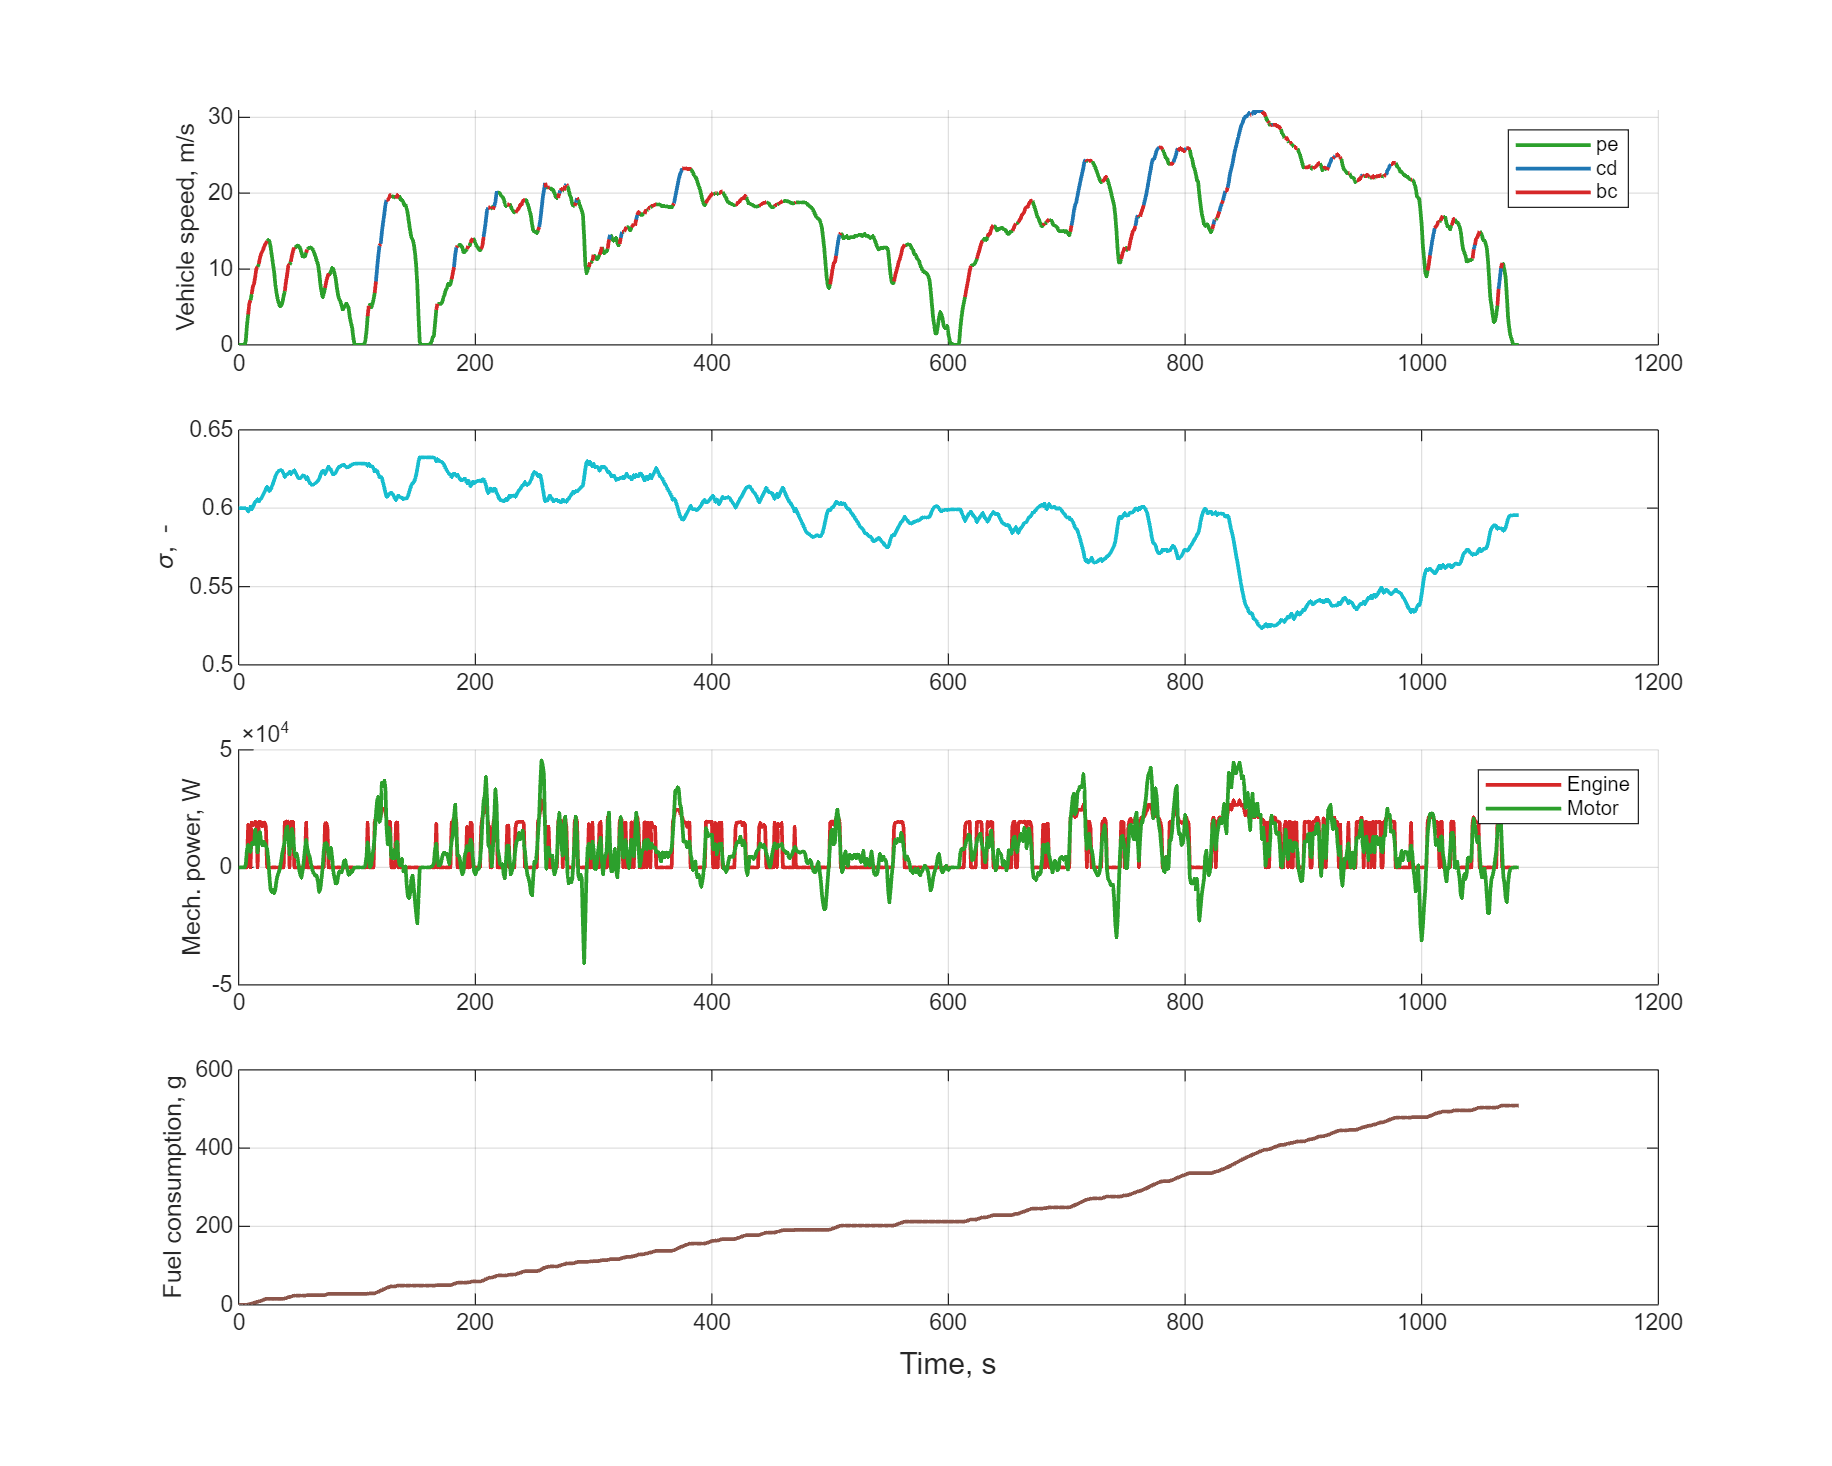

            end
        end
    end
end


## Simulation with the calibrated equivalence factor

After calibrating the two initial equivalence factors, we run the **bisection algorithm** to find the optimal equivalence factor that minimizes the difference between the final and initial SoC.

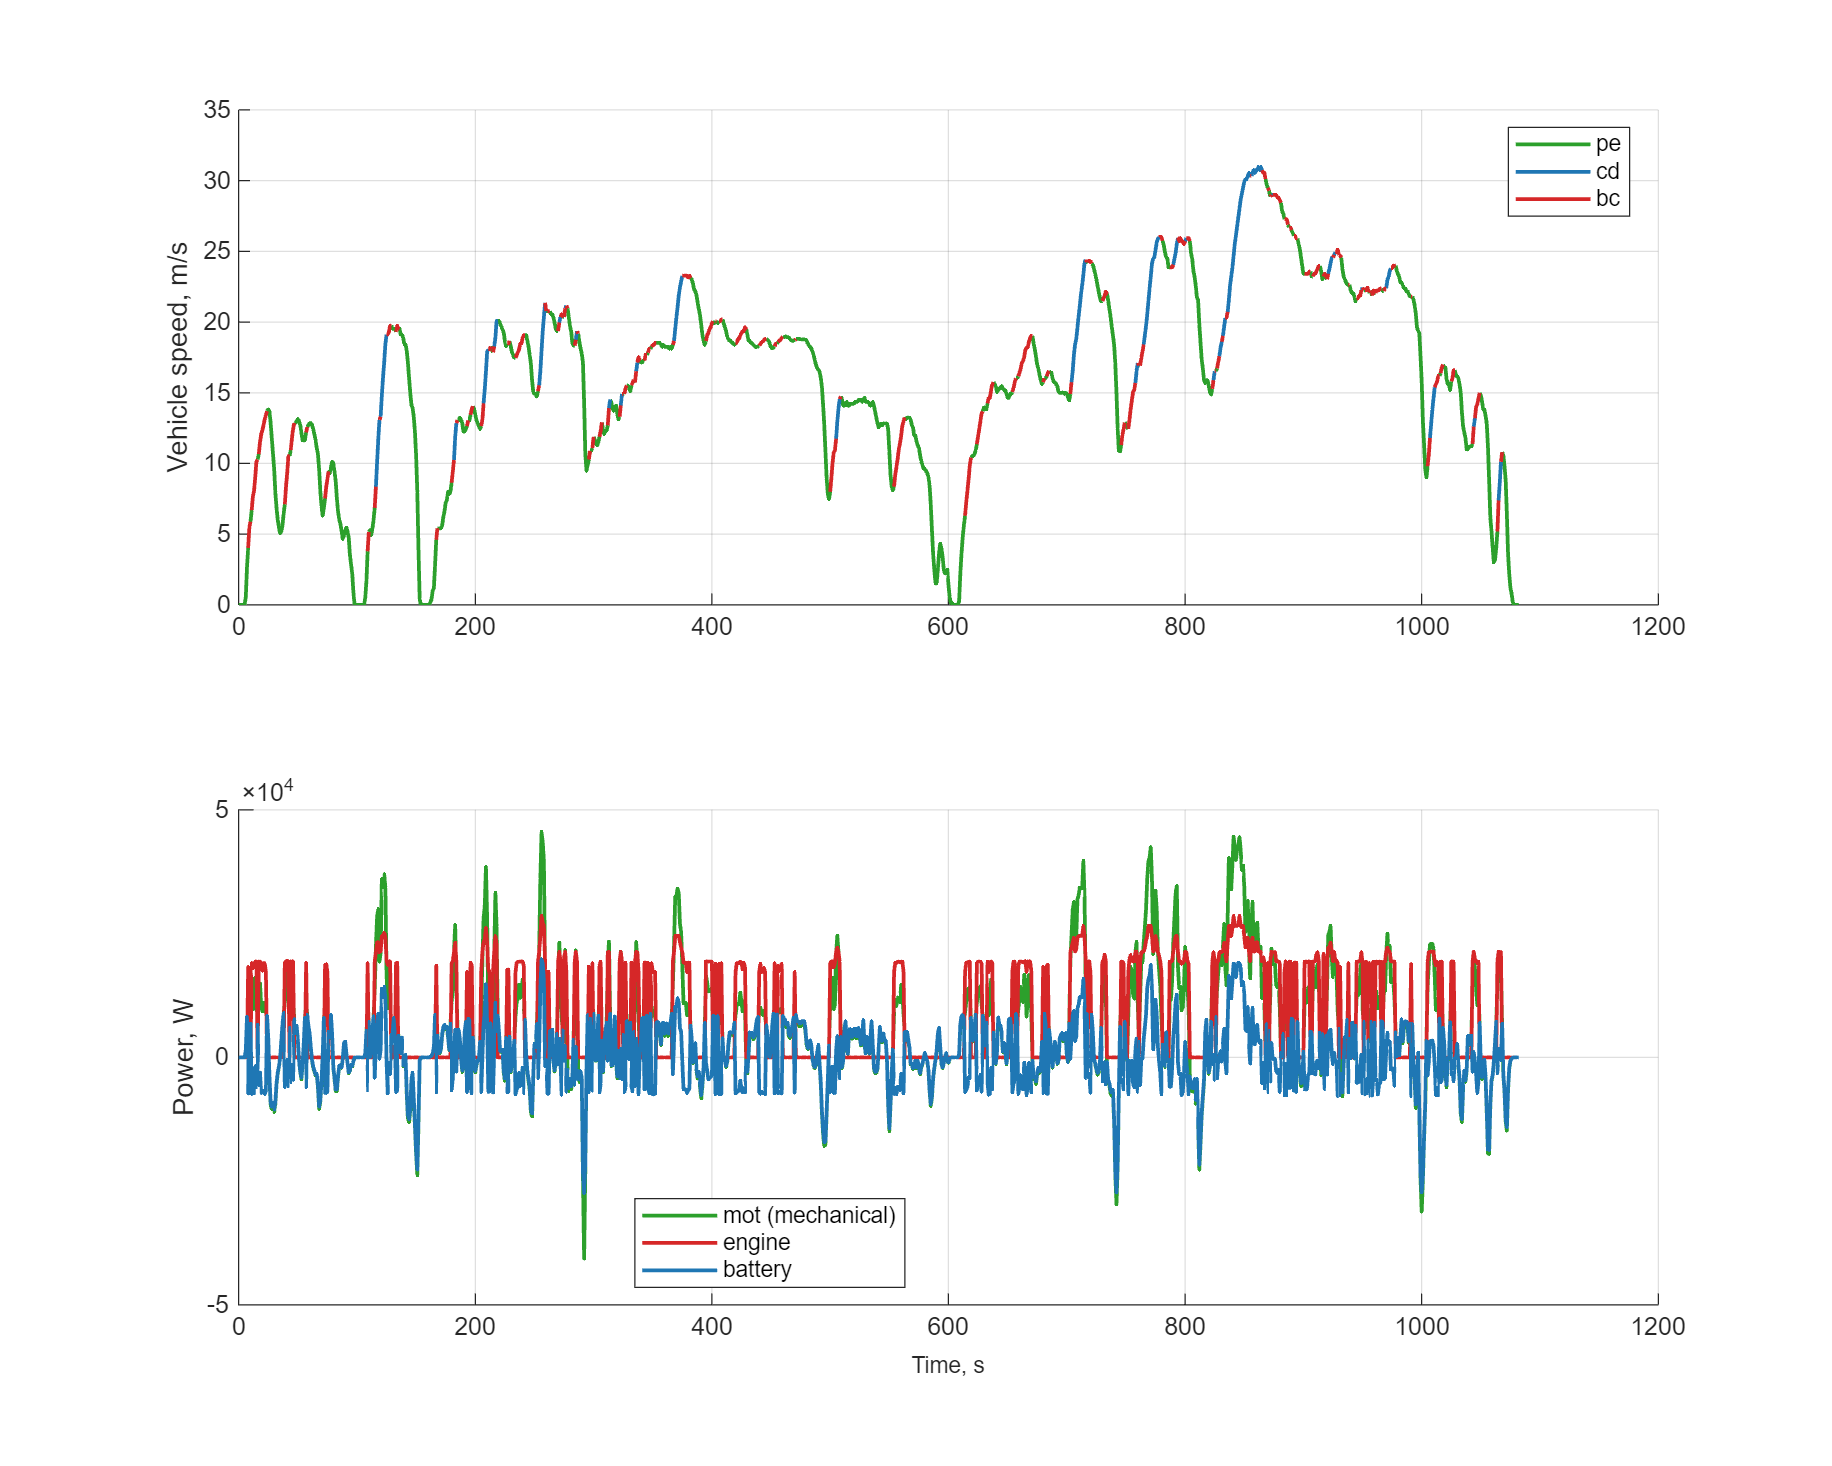

eqFactor_opt = bisectionAlgorithm(vehSpd, vehAcc, time, veh);

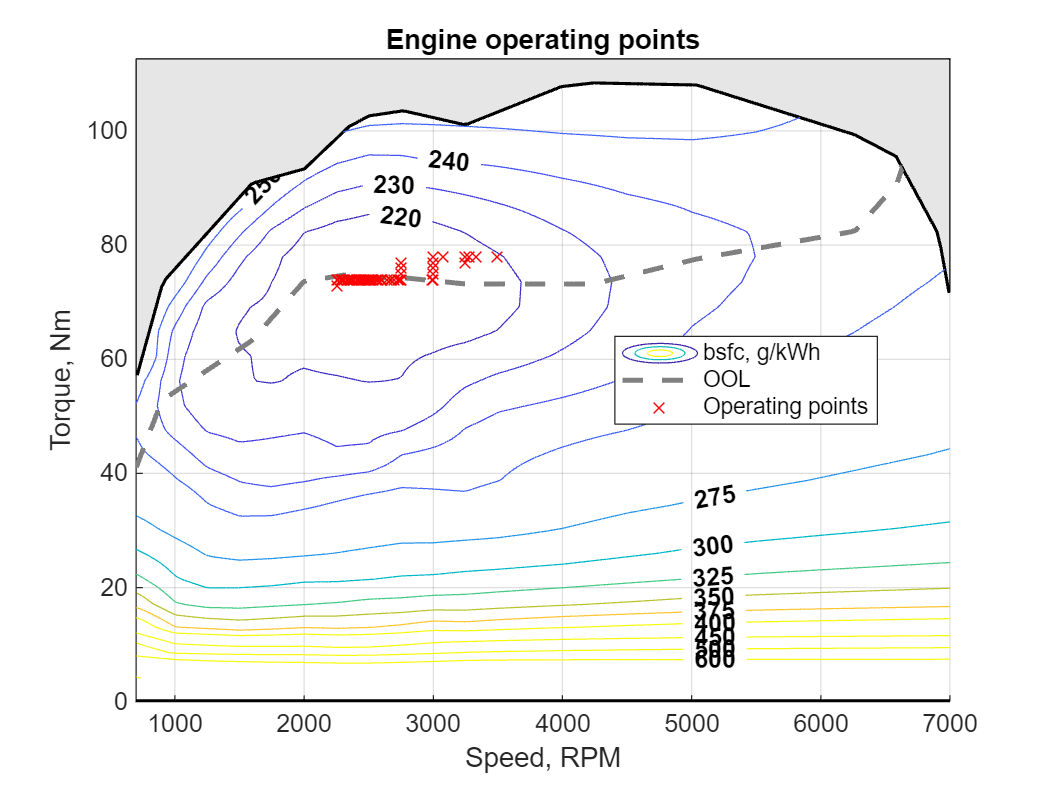

fprintf("Optimal Equivalence Factor: %.4f ", eqFactor_opt);
[psiC, stageCost, prof] = run_simulation(eqFactor_opt, time, vehSpd, vehAcc, veh);
fprintf("ΔSoC: %.4f ", psiC);

The optimal equivalence factor obtained is **2.6375**, with a corresponding ΔSoC of** -0.0045**, which satisfies the set tolerance requirement.

In addition to the SoC deviation (ΔSoC), the variables `stageCost` and `prof` are also extracted during the simulation.

This data will be used for further analysis and post-processing.

## Saving results and Post-Processing

We then **save** all the necessary data in a file called “results.mat” and show the graphs useful for studying the hybrid part.

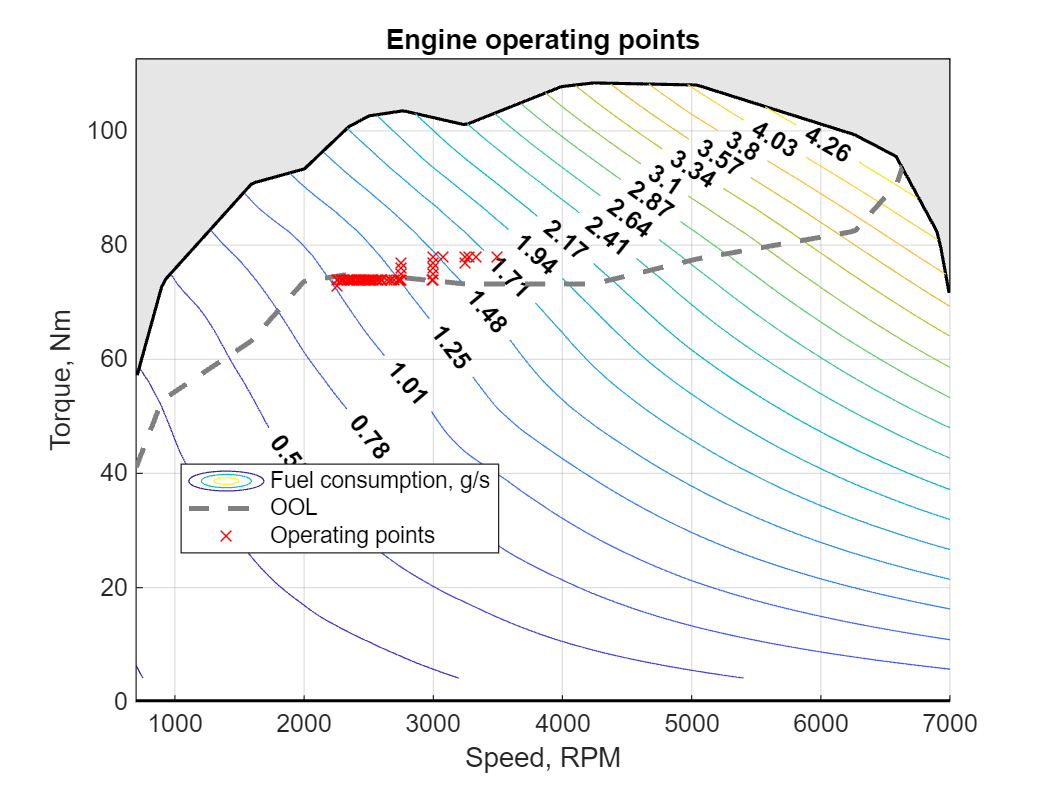

% Transform the non-scalar struct containing time profiles into scalar
% structs; this makes their manipulation easier.

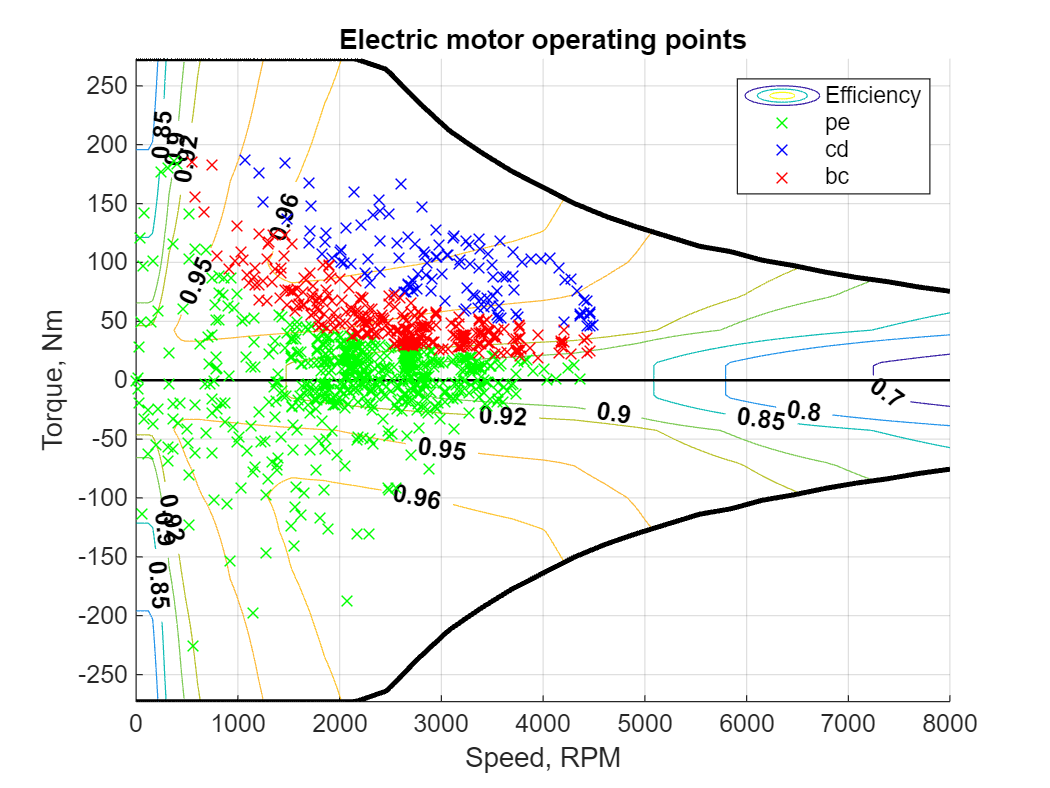


prof = structArray2struct(prof);

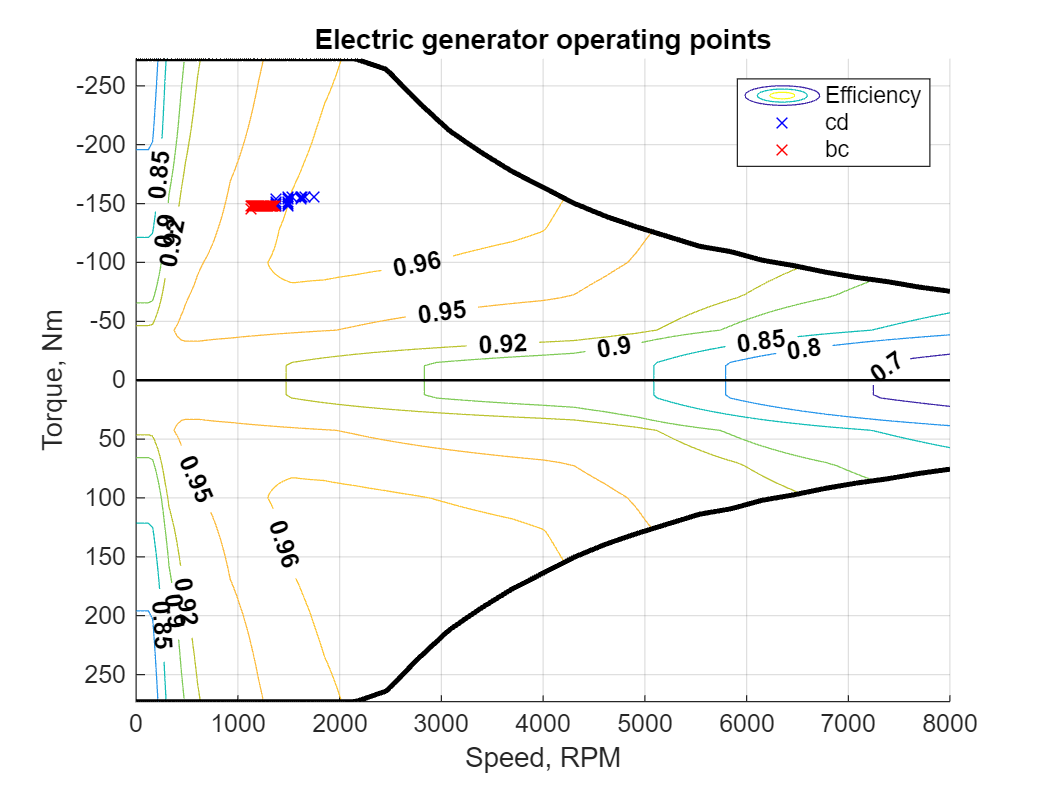

% Compute total fuel consumption
fuelConsumption = sum(prof.fuelFlwRate) * 1e-3; % [kg]


% Compute fuel economy in liters per 100 km
distance = trapz(time, vehSpd) * 1e-3; % [km]
fuelEconomy = fuelConsumption / veh.eng.fuelDensity / distance * 100; % [l/100km]

% Print fuel consumption, fuel economy and final SOC
finalSOC = prof.battSOC(end);
fprintf("Fuel consumption: %.2f kg\n", fuelConsumption);
fprintf("Fuel economy: %.2f l/100km\n", fuelEconomy);
fprintf("Final SOC: %.3f\n", finalSOC );
% Store results
save("results.mat", "prof", "stageCost");

% Display the main Time Profiles (Vehicle speed, SOC, Mechanical Power, Fuel Consumption)
mainProfiles(prof);
% Display other Time Profiles (Motor Power, ICE Power, Battery Power)
powerProfiles(prof, ["mot_mech", "eng", "batt"]);

% Generate and display the engine 'bsfc' map with power flow based on the exprimental data 
engMapWithPF(veh.eng, prof, 'bsfc');
% Generate and display the engine 'fuel consumption' map with power flow based on the exprimental data 
engMapWithPF(veh.eng, prof, 'fc');
% Generate and display the electrical motor map with power flow based on the experimental data
emMapWithPF(veh.mot, prof, 'mot', 'all');
% Generate and display the electrical generator map with power flow based on the experimental data
emMapWithPF(veh.mot, prof, 'gen', 'all');

## The ECMS controller

Describe your implementation of the ecms controller, by using code comments and this text section. **You will not get full marks if your function is not documented appropriately.**

In particular:

- Describe all inputs and outputs and why you need them.

- Name/briefly describe any other parameter that you create.

- Clearly explain in plain text how your controller works.

Remember that your ECMS must enforce the condition that the SOC never exceeds the following upper and lower thresholds:

- $\sigma_\mathrm{up} = 0.8$,

-  $\sigma_\mathrm{lo} = 0.4$.

Also, not that this section *must* come at the end of the live script, or your function will not be properly recognized by the preceding part of the script. Local functions, including this one and any other function that you may want to define, must always be defined at the end of your script.

function [engSpd, engTrq] = ecmsControl(SOC, vehSpd, vehAcc, eqFactor, veh)

engSpd_set = [0, veh.eng.idleSpd:veh.eng.maxSpd];

MaxTrq = max(veh.eng.maxTrq.Values);
engTrq_set = 0:MaxTrq;

[engSpd_grid, engTrq_grid] = ndgrid(engSpd_set, engTrq_set);

[SOC_next, stageCost, unfeas] = ...
    hev_cell_model({SOC}, {engSpd_grid, engTrq_grid}, {vehSpd, vehAcc}, veh);

SOC_dot = (SOC_next{1} - SOC) / veh.dt;

socUnfeas = (SOC_next{1} > 0.8) | (SOC_next{1} < 0.4);

eqConsumption = stageCost - eqFactor * (veh.batt.nomEnergy * 3600 / ...
    (veh.eng.fuelLHV / 1000)) * SOC_dot + unfeas*1e5 + socUnfeas*1e5;

% Trova l'indice del minimo
[~, linear_index] = min(eqConsumption(:));
[row_idx, col_idx] = ind2sub(size(eqConsumption), linear_index);


engSpd = engSpd_grid(row_idx, col_idx);
engTrq = engTrq_grid(row_idx, col_idx);
end


In this section we perform ecms control in order to evaluate **psi**, as well as the difference between the final and initial state of charge, which as mentioned above will be useful in evaluating the optimal equivalence factor due to the bisection algorithm. 

function [psi, stageCost, prof] = run_simulation(eqFactor, time, vehSpd, vehAcc, veh)
SOC(1) = 0.6;
for n = 1:length(time)
    [engSpd(n), engTrq(n)] = ecmsControl(SOC(n), vehSpd(n), vehAcc(n), eqFactor, veh);
    [SOC(n+1), stageCost(n), unfeas(n), prof(n)] = ...
        hev_model(SOC(n), [engSpd(n), engTrq(n)], [vehSpd(n), vehAcc(n)], veh);
end
psi = SOC(end)-SOC(1);
end 

This program was the **initial idea** of how to proceed with the development of ecms control. However, the main problem with this was the limitedness of the engine speed and torque values taken and especially the **slowness** of the program, given the two **for cycles**. Therefore in the final control in line 105 the use of the “hev cell model” was implemented to make the program faster and more accurate, thus giving the possibility of selecting many more values.


% function [engSpd, engTrq] = ecmsControl(SOC, vehSpd, vehAcc, s, veh)
% 
% MaxTrq = max(veh.eng.maxTrq.Values);
% 
% num_spd_points = 9; % Numero di punti per la velocità (RIGHE)
% num_Trq_points = 10;     % Numero di punti per la coppia (COLONNE)
% 
% engSpd_values = linspace(veh.eng.idleSpd, veh.eng.maxSpd, num_spd_points); % [rad/sec] Values of engine speed
% engSpd_values = [0,engSpd_values];
% num_spd_points = length(engSpd_values);
% engTrq_values = linspace(0, MaxTrq, num_Trq_points); 
% 
% % Matrici
% eqConsumption = NaN(length(engSpd_values), length(engTrq_values));
% 
% for i = 1:length(engSpd_values)
%     for j = 1:length(engTrq_values)
%         engSpd = engSpd_values(i);
%         engTrq = engTrq_values(j);
% 
%         % Chiamata al modello
%         [SOC_next, stageCost, unfeas] = hev_model(SOC, [engSpd; engTrq], [vehSpd; vehAcc], veh);
% 
%         socUnfeas = (SOC_next > 0.8) || (SOC_next < 0.4);
% 
%         if unfeas || socUnfeas
%             eqConsumption(i,j) = 10e6; % unfease
%             continue
%         end
% 
%         % Calcolo SOC_dot
%         SOC_dot = (SOC_next(1) - SOC(1)) / veh.dt;
% 
%         % Costo equivalente
%         eqConsumption(i,j) = stageCost - s * (veh.batt.nomEnergy * 3600 / (veh.eng.fuelLHV / 1000)) * SOC_dot;
%     end
% end
% 
% % Trova l'indice del minimo
% [~, linear_index] = min(eqConsumption(:));
% [row_idx, col_idx] = ind2sub(size(eqConsumption), linear_index);
% 
% 
% engSpd = engSpd_values(row_idx);
% engTrq = engTrq_values(col_idx);
% 
% end

